# create downsampled vector of all aluminum times without the artifact times

params = '/home/ben/Z/Parameters_files/FVB/FVB103_270721_849.m';
run(params)

experiment = auditory_ephys_exp(params);

Choose csv file for the whisking camera
Choose csv file for the face camera


data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
aud_data = data.Data.Data.mapped(32 + mic,:)

aud_data = 1×53851648 int16 row vector
   309   321   303   351   341   295   297   320   317   298   313   337   329   323   403   379   373   293   275   291   350   357   351   391   399   375   337   303   305   297   333   381   387   323   321   363   341   323   295   353   306   233   269   328   325   297   305   321   319   307


% find time samples in video based on whiskers for both whiskers and face
whiskingStart = experiment.Cams.whsiking.csv_start_frame

whiskingStart = 398

%expLength = length(data.Data.Data.mapped)

Unable to resolve the name data.Data.Data.mapped.

whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)
whiskingVector = [whiskingStart:whiskingEnd]
sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

[~,faceStart] = min(abs(experiment.Cams.face.csv_aligned_frames - sampleVector(1)))
faceVector = [faceStart:faceStart+length(whiskingVector)-1]

% Extract aluminum times
artifactStart = experiment.Conditions.artifact_times(2) * 30

artifactStart = 75000

artifactEnd = experiment.Conditions.artifact_times(1) * 30

artifactEnd = 90000

all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = 33×2 int64 matrix
    4786818    6511339
    6676339    8400861
    8565861   10290384
   10455384   12173912
   12338912   14051438
   14216438   15928965
   16093965   17818491
   17983491   19696063
   19861063   21573592
   21738592   23463119


aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)

aluminumTimes = 8×2 int64 matrix
    4786818    6511339
   14216438   15928965
   16093965   17818491
   19861063   21573592
   21738592   23463119
   25505648   27224177
   59676650   61389170
   61554170   63278688


% create idx vector for aluminum
aluminumInd = []


aluminumInd =

     []



for al = 1:length(aluminumTimes)
    tempInd = find(sampleVector > aluminumTimes(al,1) & sampleVector < aluminumTimes(al,2))
    aluminumInd = [aluminumInd;tempInd]
end

tempInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       188400
      188401
      188402
      188403
      188404
      188405
      188406
      188407
      188408
      188409


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       213413
      213414
      213415
      213416
      213417
      213418
      213419
      213420
      213421
      213422


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       263610
      263611
      263612
      263613
      263614
      263615
      263616
      263617
      263618
      263619


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       288623
      288624
      288625
      288626
      288627
      288628
      288629
      288630
      288631
      288632


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       338819
      338820
      338821
      338822
      338823
      338824
      338825
      338826
      338827
      338828


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       794101
      794102
      794103
      794104
      794105
      794106
      794107
      794108
      794109
      794110


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


tempInd =       819115
      819116
      819117
      819118
      819119
      819120
      819121
      819122
      819123
      819124


aluminumInd =        62758
       62759
       62760
       62761
       62762
       62763
       62764
       62765
       62766
       62767


% create samplevector for aluminum
aluminumVector = sampleVector(aluminumInd)

aluminumVector =      4786826
     4786903
     4786975
     4787053
     4787131
     4787212
     4787278
     4787360
     4787435
     4787504


% create video frame whisker vector
aluminumWhiskerVector = whiskingVector(aluminumInd)'

aluminumWhiskerVector =        63155
       63156
       63157
       63158
       63159
       63160
       63161
       63162
       63163
       63164


% create video frame face vector
aluminumFaceVector = faceVector(aluminumInd)'

aluminumFaceVector =        63170
       63171
       63172
       63173
       63174
       63175
       63176
       63177
       63178
       63179


## **create matrix for prediction with linear regression**

### **The model is a matrix with the following rows as variables and columuns as observations:**

- ** Encoder**

- **whiskingMotion_1**

- **whisking motSVD_0 (10 first)**

- **whisking motSVD_1 (10 first)**

- **faceMotion_1**

- **face motSVD_1 (10 first)**

- **Running from face camera**

**Predictions should be done on a matrix ordered the same why**

**The output will be a vector of the sound from open ephys sampled by the sampleVector and threshold **

% get the sound vector 
%aud_data = data.Data.Data.mapped(34,:)

[b,a] = butter(3,[10]/15000,'high')

b =     0.9979   -2.9937    2.9937   -0.9979


a =     1.0000   -2.9958    2.9916   -0.9958


aud_data = filtfilt(b,a,double(aud_data))

aud_data = 	1.0e+03 *

   -0.0038   -0.0048    0.0103    0.0303   -0.0547   -0.0136   -0.0266   -0.0296    0.0284   -0.0275   -0.0175    0.0185    0.0636    0.0176   -0.0374    0.0237   -0.0893   -0.0983   -0.0353    0.0008   -0.0222   -0.0172    0.0039   -0.0251   -0.0011   -0.0001   -0.0290    0.0270    0.0230    0.0051   -0.0209   -0.0139    0.0302    0.0212    0.0362    0.0022   -0.0247   -0.0127    0.0253    0.0194    0.0314   -0.0346   -0.0426   -0.0325   -0.0205   -0.0665   -0.0454   -0.0524    0.0036    0.0187


% get the aluminum sound vector 
%aud_data = aud_data(aluminumVector)

% clean artifacts clipping
aud_data(aud_data > 1000 | aud_data < -1000) = 0;

% clean data below threshold
aud_data = abs(aud_data)

aud_data =     3.7865    4.7572   10.2721   30.3015   54.6692   13.6399   26.6105   29.5812   28.4482   27.5225   17.4931   18.5362   63.5656   17.5949   37.3757   23.6536   89.3170   98.2877   35.2583    0.7710   22.1996   17.1703    3.8591   25.1115    1.0822    0.0528   29.0235   27.0059   23.0353    5.0646   20.9060   13.8766   30.1527   21.1821   36.2115    2.2408   24.7298   12.7004   25.3289   19.3583   31.3877   34.5830   42.5536   32.5242   20.4949   66.4655   45.4362   52.4068    3.6226   18.6519


aud_data = normalize(aud_data,'range')

aud_data =     0.0038    0.0048    0.0103    0.0303    0.0547    0.0136    0.0266    0.0296    0.0284    0.0275    0.0175    0.0185    0.0636    0.0176    0.0374    0.0237    0.0893    0.0983    0.0353    0.0008    0.0222    0.0172    0.0039    0.0251    0.0011    0.0001    0.0290    0.0270    0.0230    0.0051    0.0209    0.0139    0.0302    0.0212    0.0362    0.0022    0.0247    0.0127    0.0253    0.0194    0.0314    0.0346    0.0426    0.0325    0.0205    0.0665    0.0454    0.0524    0.0036    0.0187


experiment.sound_events.fullSound = aud_data;

aud_data_cleaned = aud_data(aluminumVector)

aud_data_cleaned =     0.0133    0.0908    0.0522    0.0062    0.0101    0.0369    0.0210    0.0610    0.0009    0.0111    0.0311    0.0052    0.0053    0.0303    0.0374    0.0406    0.0215    0.0045    0.0195    0.0244    0.0544    0.0004    0.0204    0.0525    0.0235    0.0435    0.0646    0.0287    0.0167    0.0028    0.0041    0.0309    0.0452    0.0207    0.0206    0.0225    0.0087    0.0498    0.0711    0.0400    0.0540    0.0079    0.0462    0.0842    0.0263    0.0057    0.0343    0.0323    0.0223    0.0447


%aud_data_cleaned(aud_data_cleaned < 0.1) = 0

figure; plot(aud_data_cleaned)

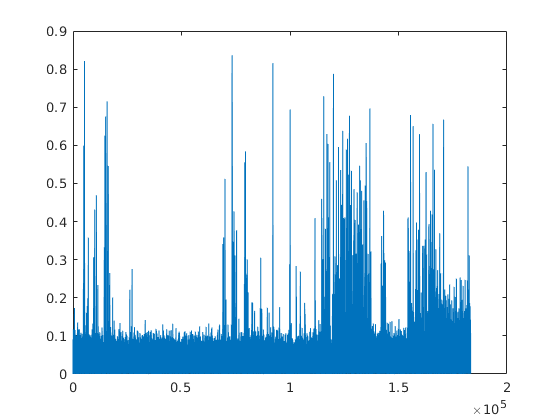

% get encoder data and high pass filter 
encoder_data = data.Data.Data.mapped(32 + encoder,:)

[b,a] = butter(3,[2]/30000,'high')
encoder_data = filtfilt(b,a,double(encoder_data))

% add encoder to the modal and prediction matrices

encoder_data = 1×53851648 int16 row vector
   5493   5499   5503   5494   5491   5491   5499   5499   5503   5491   5490   5498   5497   5486   5503   5497   5503   5487   5491   5495   5498   5501   5499   5497   5503   5501   5495   5499   5505   5497   5493   5505   5504   5504   5495   5498   5493   5502   5499   5489   5502   5497   5501   5496   5494   5499   5501   5494   5496   5499


modelMatrix = encoder_data(aluminumVector)

b =     0.9998   -2.9994    2.9994   -0.9998


a =     1.0000   -2.9996    2.9992   -0.9996


predictionMatrix = encoder_data(sampleVector)

encoder_data = 	1.0e+04 *

   -0.0004    0.0002    0.0006   -0.0003   -0.0006   -0.0006    0.0002    0.0002    0.0006   -0.0006   -0.0007    0.0001    0.0000   -0.0011    0.0006    0.0000    0.0006   -0.0010   -0.0006   -0.0002    0.0001    0.0004    0.0002    0.0000    0.0006    0.0004   -0.0002    0.0002    0.0008    0.0000   -0.0004    0.0008    0.0007    0.0007   -0.0002    0.0001   -0.0004    0.0005    0.0002   -0.0008    0.0005    0.0000    0.0004   -0.0001   -0.0003    0.0002    0.0004   -0.0003   -0.0001    0.0002


% import the whisking moiton vectors
[file,path] = uigetfile();

modelMatrix = 	1.0e+04 *

   -0.1276   -0.1223   -0.1159   -0.1113   -0.1059   -0.1000   -0.0962   -0.0914   -0.0862   -0.0824   -0.0734   -0.0705   -0.0656   -0.0625   -0.0563   -0.0512   -0.0477   -0.0436   -0.0375   -0.0349   -0.0296   -0.0239   -0.0217   -0.0170   -0.0129   -0.0092   -0.0052   -0.0008    0.0014    0.0049    0.0078    0.0133    0.0156    0.0202    0.0227    0.0253    0.0279    0.0303    0.0351    0.0378    0.0409    0.0423    0.0461    0.0470    0.0505    0.0503    0.0537    0.0557    0.0578    0.0585


cd(path)

predictionMatrix = 	1.0e+04 *

    0.0003   -0.0007   -0.0003   -0.0007    0.0005    0.0013    0.0002    0.0005    0.0009   -0.0006   -0.0005    0.0009    0.0005    0.0003   -0.0004   -0.0019    0.0001    0.0010    0.0011   -0.0013   -0.0003   -0.0006   -0.0000    0.0005   -0.0009    0.0006   -0.0002   -0.0004    0.0001    0.0005    0.0013   -0.0007    0.0012    0.0004    0.0004    0.0004    0.0000   -0.0006    0.0000   -0.0008   -0.0008    0.0000   -0.0014   -0.0004    0.0003   -0.0004    0.0000   -0.0004   -0.0005    0.0000


load(file,'motSVD_1','motion_1','motSVD_0')
try
    load(file,'motSVD_2')
catch 
    'no motSVD_2'
end

if ~isempty(motSVD_0)% add motion and motSVDs to the modal and prediciton matrices
    modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
    predictionMatrix(2,:) = motion_1(whiskingVector)
    modelMatrix(3:12,:) = motSVD_0(aluminumWhiskerVector,1:10)'
    predictionMatrix(3:12,:) = motSVD_0(whiskingVector,1:10)'
    modelMatrix(13:22,:) = motSVD_1(aluminumWhiskerVector,1:10)'
    predictionMatrix(13:22,:) = motSVD_1(whiskingVector,1:10)'
    ind = 23
elseif exist('motSVD_2')
    modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
    predictionMatrix(2,:) = motion_1(whiskingVector)
    modelMatrix(3:12,:) = motSVD_1(aluminumWhiskerVector,1:10)'
    predictionMatrix(3:12,:) = motSVD_1(whiskingVector,1:10)'
    modelMatrix(13:22,:) = motSVD_2(aluminumWhiskerVector,1:10)'
    predictionMatrix(13:22,:) = motSVD_2(whiskingVector,1:10)'
    ind = 23
else
    modelMatrix(2,:) = motion_1(aluminumWhiskerVector)
    predictionMatrix(2,:) = motion_1(whiskingVector)
    modelMatrix(3:12,:) = motSVD_1(aluminumWhiskerVector,1:10)'
    predictionMatrix(3:12,:) = motSVD_1(whiskingVector,1:10)'
    ind = 13
end


modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

ind = 23

% import data from face video
clear motion_1 motion_0 motSVD_1 motSVD_0
[file,path] = uigetfile();
cd(path)
load(file, 'motSVD_1','motion_1','running_0')

% add motion and motSVDs to the modal and prediciton matrices
modelMatrix(ind,:) = motion_1(aluminumFaceVector)

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix(ind,:) = motion_1(faceVector)

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

modelMatrix(ind+1:ind+10,:) = motSVD_1(aluminumFaceVector,1:10)'

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix(ind+1:ind+10,:) = motSVD_1(faceVector,1:10)'

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

modelMatrix(ind+11:ind+12,:) = running_0(aluminumFaceVector,1:2)'

modelMatrix = 	1.0e+05 *

   -0.0128   -0.0122   -0.0116   -0.0111   -0.0106   -0.0100   -0.0096   -0.0091   -0.0086   -0.0082   -0.0073   -0.0070   -0.0066   -0.0062   -0.0056   -0.0051   -0.0048   -0.0044   -0.0038   -0.0035   -0.0030   -0.0024   -0.0022   -0.0017   -0.0013   -0.0009   -0.0005   -0.0001    0.0001    0.0005    0.0008    0.0013    0.0016    0.0020    0.0023    0.0025    0.0028    0.0030    0.0035    0.0038    0.0041    0.0042    0.0046    0.0047    0.0051    0.0050    0.0054    0.0056    0.0058    0.0058
    0.7728    0.8099    0.8792    0.8802    0.8764    0.8335    0.7195    0.5331    0.4316    0.3974    0.3824    0.3592    0.3856    0.4339    0.4512    0.4301    0.4657    0.4683    0.4368    0.4050    0.3929    0.3835    0.3873    0.4080    0.4126    0.4141    0.4214    0.4127    0.3975    0.3765    0.3836    0.3718    0.4103    0.4159    0.4166    0.4310    0.4133    0.4094    0.4021    0.4039    0.4496    0.4513    0.4352    0.4475    0.4218    0.4157    0.3900   

predictionMatrix(ind+11:ind+12,:) = running_0(faceVector,1:2)'

predictionMatrix = 	1.0e+05 *

    0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001    0.0000    0.0000    0.0001   -0.0001   -0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0002    0.0000    0.0001    0.0001   -0.0001   -0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1427    0.1630    0.1763    0.3011    0.1893    0.2040    0.1783    0.1402    0.1381    0.1680    0.2200    0.1932    0.1715    0.1726    0.1664    0.1923    0.1844    0.1514    0.1814    0.1697    0.1693    0.1864    0.1775    0.1855    0.1917    0.1889    0.1942    0.1912    0.1719    0.1848    0.1732    0.2170    0.1997    0.2137    0.1804    0.1674    0.1899    0.1762    0.1936    0.1947    0.1942    0.1786    0.1890    0.1666    0.1876    0.1862    0.20

% save the model and prediction vectors 
save('model_matrices.mat','experiment','modelMatrix',"aud_data_cleaned",'predictionMatrix','sampleVector','aluminumWhiskerVector')

% load model and prediction if needed
%cd('/home/ben/Z/FVB/270721/849')                   
load('model_matrices.mat')

% create traintest spli idx for testing model
modelPart = cvpartition(length(modelMatrix),"HoldOut",0.1)

modelPart = Hold-out cross validation partition
   NumObservations: 183261
       NumTestSets: 1
         TrainSize: 164935
          TestSize: 18326

idxTrain = training(modelPart)

idxTrain = 183261×1 logical array
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1


idxTest = test(modelPart)

idxTest = 183261×1 logical array
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0


% split data to train test
modelTrain = modelMatrix(:,idxTrain)

modelTrain = 	1.0e+06 *

   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1034    0.1023    0.1053    0.1032    0.1047    0.1071    0.1066    0.1033    0.1034    0.1070    0.1057    0.1075    0.1050    0.1013    0.0990    0.1020    0.1013    0.1067    0.1047    0.1021    0.0995    0.1005    0.1013    0.1030    0.1041    0.1036    0.1039    0.1034    0.1003    0.1029    0.1029    0.1014    0.1025    0.1052    0.1133    0.1106    0.1110    0.1087    0.1055    0.1018    0.1039    0.1030    0.1007    0.1014    0.1047    0.0997    0.1030    

modelTest = modelMatrix(:,idxTest)

modelTest = 	1.0e+06 *

   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1010    0.1068    0.1042    0.1031    0.1020    0.1012    0.1005    0.1008    0.1134    0.1159    0.1188    0.0965    0.1139    0.1102    0.1022    0.1065    0.1029    0.1004    0.0988    0.1030    0.1039    0.0953    0.1053    0.1186    0.1230    0.1321    0.1087    0.0998    0.1060    0.1040    0.1019    0.1013    0.1009    0.1049    0.1105    0.1028    0.1058    0.1249    0.1185    0.1120    0.1074    0.1011    0.1174    0.1077    0.1078    0.1142    0.1108    0


aud_data_Train = aud_data_cleaned(idxTrain)

aud_data_Train =     0.0133    0.0908    0.0062    0.0101    0.0369    0.0210    0.0610    0.0009    0.0111    0.0311    0.0052    0.0053    0.0303    0.0374    0.0406    0.0215    0.0045    0.0195    0.0244    0.0544    0.0004    0.0204    0.0525    0.0235    0.0435    0.0646    0.0287    0.0167    0.0028    0.0041    0.0309    0.0452    0.0207    0.0206    0.0225    0.0087    0.0498    0.0711    0.0400    0.0540    0.0079    0.0462    0.0842    0.0263    0.0057    0.0343    0.0323    0.0223    0.0447    0.0323


aud_data_test = aud_data_cleaned(idxTest)

aud_data_test =     0.0522    0.0082    0.0338    0.0461    0.0620    0.0060    0.0783    0.0127    0.0689    0.0586    0.0030    0.0443    0.0319    0.0320    0.0040    0.0759    0.0476    0.0325    0.0287    0.0394    0.0458    0.0014    0.0140    0.0132    0.0251    0.0322    0.0046    0.0221    0.0182    0.0002    0.0062    0.0617    0.0407    0.0364    0.0136    0.0683    0.0227    0.0188    0.0237    0.0145    0.0485    0.0355    0.0142    0.0309    0.0260    0.0090    0.0143    0.0060    0.0079    0.0109


%aud_data_cleaned = normalize(aud_data_cleaned,'range')

% savr model to the experiment object
experiment.predictionModel = trainedModel;

% Get predictions from regression learner (bagged tree ensamble)
y = trainedModel.predictFcn(predictionMatrix)

% find all y values aboe threshold and find the start of each event 

[times] = event_detection(y,500*0.4)

y =     0.0324
    0.0318
    0.0316
    0.0321
    0.0380
    0.0359
    0.0346
    0.0290
    0.0318
    0.0307


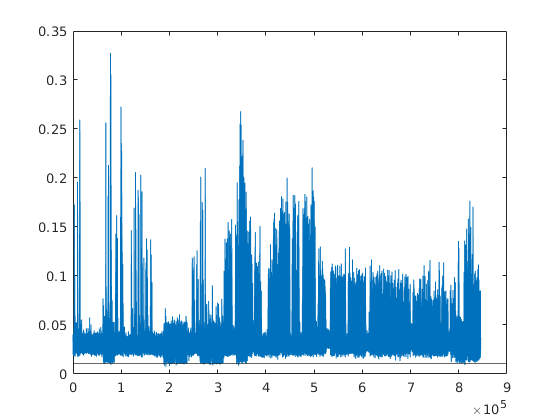

thr = 0.0650

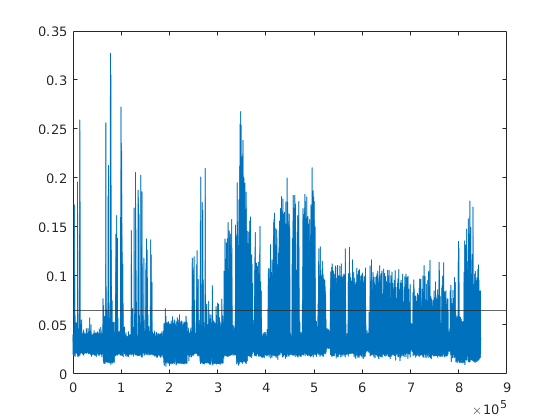

thr = 0.0650

times =         2455        2759        3563        9317       13103       13620       14033       14587       62245       63429       67529       68865       69350       72273       72734       73451       74194       77050       77774       78374       78859       79582       81020       81230       88228       88732       89139       89645       90332       90948       91504       92162       98514       98946       99373       99825      100271      100846      101379      102079      102937      103838      120904      121367      123557      126598      129469      130160      130686      131542



% find events sample time
times_prediction = times

times = sampleVector(times);

experiment.predictedSound.y = y

times_prediction =         2455        2759        3563        9317       13103       13620       14033       14587       62245       63429       67529       68865       69350       72273       72734       73451       74194       77050       77774       78374       78859       79582       81020       81230       88228       88732       89139       89645       90332       90948       91504       92162       98514       98946       99373       99825      100271      100846      101379      102079      102937      103838      120904      121367      123557      126598      129469      130160      130686      131542


experiment.predictedSound.sampleVector = sampleVector
experiment.predictedSound.events.all = times_prediction

% Add the events top the experiment object

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


experiment.sound_events.all = times

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


artifactStart = experiment.Conditions.artifact_times(2) * 30

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


artifactEnd = experiment.Conditions.artifact_times(1) * 30
all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = all_times(1:22,:)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_757'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


times = experiment.sound_events.all;

artifactStart = 75000

times_prediction = experiment.predictedSound.events.all

artifactEnd = 90000

`Divide the events to the experiment condition`

% Aluminum times

all_times = 27×2 int64 matrix
    4798592    6517119
    6682119    8406643
    8571643   10290171
   10455171   12173700
   12338700   14051228
   14216228   15934759
   16099759   17824286
   17989286   19701859
   19866859   21585390
   21750390   23474914


aluminumTimes = all_times(experiment.Conditions.condition_classification(1:18) == 1,:)
aluminumEvents = []

all_times = 22×2 int64 matrix
    4798592    6517119
    6682119    8406643
    8571643   10290171
   10455171   12173700
   12338700   14051228
   14216228   15934759
   16099759   17824286
   17989286   19701859
   19866859   21585390
   21750390   23474914


experiment.predictedSound.events.aluminum = [];
for al = 1:length(aluminumTimes)
    tempEvents = times(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))

times_prediction =         3796        4277        5122       22191       22897       25761       26441       27095       32171       32754       33513       34681       37633       38214       39578       44586       45106       45639       46415       48550       49023       49623       50384       50878       51417       51987       52727       53171       53694       54337       54746       55360       55720       56096       56493       56992       57419       57816       58139       58506       59035       59504       60214       60804       62250       62792       63654       64049       64412       64795


    tempPredict = times_prediction(find(times > aluminumTimes(al,1) & times < aluminumTimes(al,2)))'
    aluminumEvents = [aluminumEvents;tempEvents]
    experiment.predictedSound.events.aluminum = [experiment.predictedSound.events.aluminum;tempPredict]
end

% non times

aluminumTimes = 6×2 int64 matrix
   14216228   15934759
   19866859   21585390
   25517440   27235965
   29278488   30997011
   33039531   34758095
   36800614   38525130


nonTimes = all_times(experiment.Conditions.condition_classification(1:18) == 3,:)


aluminumEvents =

     []



experiment.predictedSound.events.non = [];
nonEvents = []
for non = 1:length(nonTimes)
    tempInd = times(find(times > nonTimes(non,1) & times < nonTimes(non,2)))
    tempPredict = times_prediction(find(times > nonTimes(non,1) & times < nonTimes(non,2)))'
    nonEvents = [nonEvents;tempInd]
    experiment.predictedSound.events.non = [experiment.predictedSound.events.non;tempPredict];

tempEvents =     14340572
    14370959
    14508826
    14572308
    14616433
    14640676
    14751142
    14772081
    14793615
    14861990


tempPredict =       189902
      190307
      192143
      192989
      193577
      193900
      195372
      195651
      195938
      196849


aluminumEvents =     14340572
    14370959
    14508826
    14572308
    14616433
    14640676
    14751142
    14772081
    14793615
    14861990


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_849'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: [1×1 struct]
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     19870401
    19891117
    19953629
    19993546
    20077303
    20131713
    20176743
    20302895
    20328264
    20350173


tempPredict =       263585
      263861
      264694
      265226
      266342
      267067
      267667
      269348
      269686
      269978


aluminumEvents =     14340572
    14370959
    14508826
    14572308
    14616433
    14640676
    14751142
    14772081
    14793615
    14861990


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_849'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: [1×1 struct]
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     25519320
    25580633
    25602095
    25853279
    26163288
    26336943
    26361862
    26725238
    27174308
    27195471


tempPredict =       338842
      339659
      339945
      343292
      347423
      349737
      350069
      354911
      360895
      361177


aluminumEvents =     14340572
    14370959
    14508826
    14572308
    14616433
    14640676
    14751142
    14772081
    14793615
    14861990


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_849'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: [1×1 struct]
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     29294513
    29404155
    29428620
    29503735
    29535332
    29564155
    29597853
    29660133
    29717469
    29750720


tempPredict =       389147
      390608
      390934
      391935
      392356
      392740
      393189
      394019
      394783
      395226


aluminumEvents =     14340572
    14370959
    14508826
    14572308
    14616433
    14640676
    14751142
    14772081
    14793615
    14861990


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_849'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: [1×1 struct]
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     33047396
    33275165
    33315460
    33338502
    33381214
    33411074
    33458197
    33615954
    33636431
    33747353


tempPredict =       439142
      442177
      442714
      443021
      443590
      443988
      444616
      446718
      446991
      448469


aluminumEvents =     14340572
    14370959
    14508826
    14572308
    14616433
    14640676
    14751142
    14772081
    14793615
    14861990


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_849'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: [1×1 struct]
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     36827241
    36950160
    36983038
    37004735
    37028219
    37054631
    37182583
    37236619
    37273084
    37358339


tempPredict =       489508
      491146
      491584
      491873
      492186
      492538
      494243
      494963
      495449
      496585


aluminumEvents =     14340572
    14370959
    14508826
    14572308
    14616433
    14640676
    14751142
    14772081
    14793615
    14861990


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB103_849'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: [1×1 struct]
                   PSTHs: [1×1 struct]
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


end

% muted times
mutedTimes = all_times(experiment.Conditions.condition_classification(1:18) == 2,:)

nonTimes = 4×2 int64 matrix
    4798592    6517119
    8571643   10290171
   17989286   19701859
   23639914   25352440


experiment.predictedSound.events.muted = [];
mutedEvents = []


nonEvents =

     []



for mut = 1:length(mutedTimes)
    tempInd = times(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))
    tempPredict = times_prediction(find(times > mutedTimes(mut,1) & times < mutedTimes(mut,2)))'
    mutedEvents = [mutedEvents;tempInd]
    experiment.predictedSound.events.muted = [experiment.predictedSound.events.muted;tempPredict];
end

tempInd =      4851844
     4881489
     4908724
     4937472
     4977406
     5004030
     5046659
     5071500
     5095300
     5118557


tempPredict =        63654
       64049
       64412
       64795
       65327
       65682
       66250
       66581
       66898
       67191


nonEvents =      4851844
     4881489
     4908724
     4937472
     4977406
     5004030
     5046659
     5071500
     5095300
     5118557


tempInd =      8590095
     8837974
     8884501
     8908970
     8929757
     8952644
     8979362
     9006001
     9029866
     9053356


tempPredict =       113285
      116588
      117208
      117534
      117811
      118116
      118472
      118827
      119145
      119458


nonEvents =      4851844
     4881489
     4908724
     4937472
     4977406
     5004030
     5046659
     5071500
     5095300
     5118557


tempInd =     18006255
    18027796
    18050383
    18074774
    18097959
    18121754
    18142464
    18166780
    18189743
    18211360


tempPredict =       238745
      239032
      239333
      239658
      239967
      240284
      240560
      240884
      241190
      241478


nonEvents =      4851844
     4881489
     4908724
     4937472
     4977406
     5004030
     5046659
     5071500
     5095300
     5118557


tempInd =     23659458
    23683397
    23925047
    23966699
    24002050
    24024036
    24046774
    24141035
    24315365
    24344932


tempPredict =       314062
      314381
      317600
      318155
      318626
      318919
      319222
      320478
      322800
      323194


nonEvents =      4851844
     4881489
     4908724
     4937472
     4977406
     5004030
     5046659
     5071500
     5095300
     5118557


timeWind = 1;

mutedTimes = 8×2 int64 matrix
    6682119    8406643
   10455171   12173700
   12338700   14051228
   16099759   17824286
   21750390   23474914
   27400965   29113488
   31162011   32874531
   34923095   36635614


numBins = 20;

rasters_aluminum = {}


mutedEvents =

     []



psth_aluminum = []
for un = 1:length(experiment.Units.good.id)
    rasters_aluminum{un} = createRaster(aluminumEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])
    psth_aluminum(un,:) = psth(rasters_aluminum{un},numBins);
end

tempInd =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


tempPredict =        88342
       88703
       89194
       89557
       89893
       90200
       90481
       90774
       91077
       91388


mutedEvents =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


tempInd =     10630079
    10660705
    10687638
    10722458
    10747452
    10791278
    10812669
    10838030
    10865049
    10895743


tempPredict =       140468
      140876
      141235
      141699
      142032
      142616
      142901
      143239
      143599
      144008


mutedEvents =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


tempInd =     12347282
    12383529
    12404767
    12429086
    12510957
    12532269
    12555753
    12593431
    12624577
    12647102


tempPredict =       163346
      163829
      164112
      164436
      165527
      165811
      166124
      166626
      167041
      167341


mutedEvents =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


tempInd =     16103691
    16125682
    16148273
    16171533
    16191870
    16213336
    16255661
    16278474
    16301737
    16324929


tempPredict =       213394
      213687
      213988
      214298
      214569
      214855
      215419
      215723
      216033
      216342


mutedEvents =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


tempInd =     21766812
    21788871
    21810942
    21833753
    21855827
    21876752
    21976713
    22038703
    22079827
    22101741


tempPredict =       288847
      289141
      289435
      289739
      290033
      290312
      291644
      292470
      293018
      293310


mutedEvents =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


tempInd =     27431039
    27453479
    27476139
    27842815
    27863684
    27963942
    28041014
    28063530
    28355157
    28381652


tempPredict =       364316
      364615
      364917
      369803
      370081
      371417
      372444
      372744
      376630
      376983


mutedEvents =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


tempInd =     31185754
    31214488
    31265066
    31290206
    31502141
    31536205
    31558267
    31578456
    31600293
    31627906


tempPredict =       414338
      414721
      415395
      415730
      418554
      419008
      419302
      419571
      419862
      420230


mutedEvents =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


tempInd =     34929548
    34963472
    35027859
    35057803
    35087977
    35117167
    35147409
    35187857
    35213075
    35241438


tempPredict =       464222
      464674
      465532
      465931
      466332
      466721
      467124
      467663
      467999
      468377


mutedEvents =      6718080
     6745166
     6782015
     6809335
     6834545
     6857587
     6878678
     6900666
     6923399
     6946746


rasters_muted = {}
psth_muted = []
for un = 1:length(experiment.Units.good.id)
    rasters_muted{un} = createRaster(mutedEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_muted(un,:) = psth(rasters_muted{un},numBins);


rasters_aluminum =

  0×0 empty cell array



end


psth_aluminum =

     []



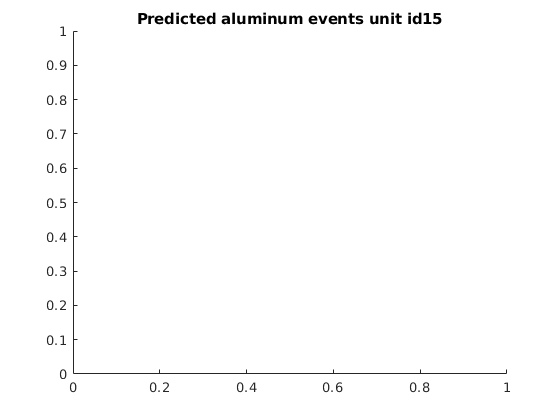

rasters_non = {}
psth_non = []
for un = 1:length(experiment.Units.good.id)
    rasters_non{un} = createRaster(nonEvents,experiment.Units.good.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])

    psth_non(un,:) = psth(rasters_non{un},numBins);
end


rasters_muted =

  0×0 empty cell array




psth_muted =

     []



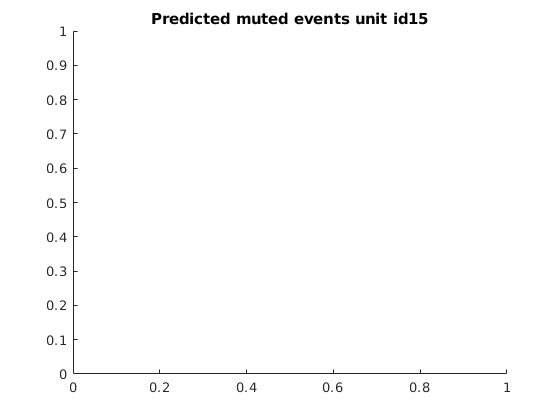

rasters_aluminumMua = {}
psth_aluminumMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_aluminumMua{un} = createRaster(aluminumEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted aluminum events unit id',num2str(un)])

    psth_aluminumMua(un,:) = psth(rasters_aluminumMua{un},numBins);
end


rasters_non =

  0×0 empty cell array



rasters_mutedMua = {}


psth_non =

     []



psth_mutedMua = []
for un = 1:length(experiment.Units.mua.id)
    rasters_mutedMua{un} = createRaster(mutedEvents,experiment.Units.mua.times(un,:),timeWind);
    title(['Predicted muted events unit id',num2str(un)])
    psth_mutedMua(un,:) = psth(rasters_mutedMua{un},numBins);

end

rasters_nonMua = {}
psth_nonMua = []
for un = 1:length(experiment.Units.mua.id)


rasters_aluminumMua =

  0×0 empty cell array



    rasters_nonMua{un} = createRaster(nonEvents,experiment.Units.mua.times(un,:),timeWind);


psth_aluminumMua =

     []



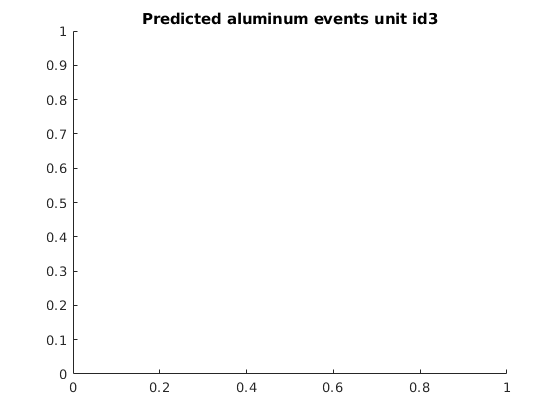

    title(['Predicted muted events unit id',num2str(un)])
    psth_nonMua(un,:) = psth(rasters_nonMua{un},numBins);
end

psth_aluminumAll = [psth_aluminum;psth_aluminumMua]


rasters_mutedMua =

  0×0 empty cell array



psth_mutedAll = [psth_muted;psth_mutedMua]


psth_mutedMua =

     []



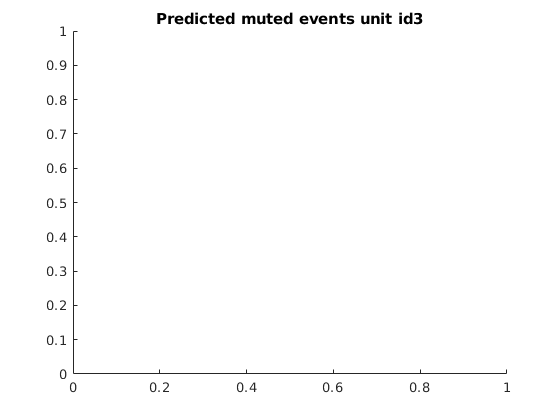

psth_nonAll = [psth_non;psth_nonMua]

aud_units = find(experiment.evokedEvents.pVal(:,2) == 1);


rasters_nonMua =

  0×0 empty cell array



[~,time_vector] = psth(rasters_non{1},numBins);


psth_nonMua =

     []



mutSTD = std(psth_mutedAll(aud_units,:))/sqrt(length(aud_units))
alumSTD = std(psth_aluminumAll(aud_units,:))/sqrt(length(aud_units))
nonSTD = std(psth_nonAll(aud_units,:))/sqrt(length(aud_units))

figure; 

psth_aluminumAll =     0.0733    0.1067    0.0800    0.0733    0.0733    0.0800    0.0667    0.0333    0.0733    0.0867    0.0933    0.0667    0.0733    0.0600    0.0667    0.0800    0.1133    0.0733    0.0533    0.0600    0.0800    0.0933    0.0800    0.1000    0.0800    0.0800    0.1067    0.1000    0.1133    0.1000    0.0667    0.0867    0.0933    0.0800    0.1067    0.0733    0.0467    0.0733    0.1000    0.0800    0.0800    0.0933    0.0867    0.0267    0.0733    0.0533    0.0800    0.0667    0.0467    0.0333
    0.0800    0.0533    0.0867    0.0533    0.0733    0.0667    0.0400    0.0667    0.0600    0.0733    0.0800    0.0333    0.0533    0.0933    0.0467    0.0467    0.0733    0.1000    0.0733    0.0400    0.0867    0.0533    0.0667    0.0867    0.0733    0.1133    0.1067    0.1267    0.0867    0.0800    0.0533    0.0533    0.0867    0.0733    0.0933    0.0600    0.0800    0.0467    0.0800    0.0867    0.0533    0.0533    0.0600    0.0800    0.0600    0.0400    0.0800    0.0667

hold on


psth_mutedAll =     0.0431    0.0489    0.0517    0.0230    0.0431    0.0259    0.0575    0.0259    0.0316    0.0374    0.0230    0.0402    0.0690    0.0460    0.0316    0.0546    0.0431    0.0316    0.0460    0.0374    0.0172    0.0201    0.0201    0.0115    0.0316    0.0316    0.0316    0.0345    0.0431    0.0431    0.0575    0.0575    0.0575    0.0489    0.0575    0.0345    0.0316    0.0632    0.0603    0.0489    0.0431    0.0546    0.0489    0.0374    0.0402    0.0374    0.0287    0.0345    0.0402    0.0517
    0.0575    0.0603    0.0489    0.0632    0.0460    0.0603    0.0460    0.0489    0.0431    0.0374    0.0603    0.0517    0.0402    0.0460    0.0517    0.0431    0.0345    0.0575    0.0517    0.0172    0.0316    0.0431    0.0402    0.0489    0.0489    0.0546    0.0287    0.0316    0.0517    0.0747    0.0546    0.0575    0.0489    0.0517    0.0690    0.0431    0.0661    0.0402    0.0460    0.0603    0.0833    0.0603    0.0575    0.0632    0.0345    0.0460    0.0546    0.0489   

plot(time_vector,mean(psth_aluminumAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Aluminum)

psth_nonAll =     0.0588    0.0654    0.0392    0.0523    0.0261    0.0261    0.0523    0.0327    0.0261    0.0261    0.0458    0.0261    0.0588    0.0065    0.0327    0.0065    0.0327    0.0261    0.0327    0.0392    0.0196    0.0327    0.0131    0.0588    0.0327    0.0392    0.0327    0.0654    0.0327    0.0588    0.0261    0.0327    0.0523    0.0065    0.0327    0.0458    0.0196    0.0327    0.0261    0.0523    0.0196    0.0523    0.0458    0.0327    0.0196    0.0784    0.0131    0.0131    0.0458    0.0392
    0.0327    0.0458    0.0523    0.0392    0.0523    0.0392    0.0523    0.0196    0.0458    0.0261    0.0261    0.0458    0.0327    0.0131    0.0327    0.0196    0.0392    0.0131    0.0588    0.0196    0.0588    0.0588    0.0523    0.0327    0.0392    0.0458    0.0523    0.0392    0.0327    0.0523    0.0196    0.0523    0.0784    0.0327    0.0719    0.0196    0.0392    0.0458    0.0458    0.0458    0.0261    0.0392    0.0458    0.0719    0.0719    0.0261    0.0131    0.0850    0

errorbar(time_vector,mean(psth_aluminumAll(aud_units,:)),alumSTD,'LineWidth',0.1,'Color',experiment.color.Aluminum)
hold on
plot(time_vector,mean(psth_mutedAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.Muted)
errorbar(time_vector,mean(psth_mutedAll(aud_units,:)),mutSTD,'LineWidth',0.1,'Color',experiment.color.Muted)
plot(time_vector,mean(psth_nonAll(aud_units,:)),'LineWidth',2,'Color',experiment.color.noObject)

mutSTD =     0.0226    0.0224    0.0224    0.0214    0.0200    0.0201    0.0187    0.0182    0.0191    0.0214    0.0197    0.0223    0.0242    0.0233    0.0211    0.0224    0.0190    0.0217    0.0240    0.0247    0.0201    0.0189    0.0243    0.0204    0.0185    0.0215    0.0208    0.0214    0.0192    0.0232    0.0220    0.0233    0.0225    0.0224    0.0211    0.0223    0.0225    0.0236    0.0229    0.0251    0.0244    0.0199    0.0173    0.0223    0.0219    0.0230    0.0199    0.0201    0.0223    0.0215


errorbar(time_vector,mean(psth_nonAll(aud_units,:)),nonSTD,'LineWidth',0.1,'Color',experiment.color.noObject)

alumSTD =     0.0241    0.0216    0.0195    0.0221    0.0248    0.0201    0.0242    0.0215    0.0219    0.0229    0.0182    0.0222    0.0243    0.0236    0.0218    0.0242    0.0235    0.0321    0.0231    0.0291    0.0264    0.0301    0.0262    0.0229    0.0299    0.0312    0.0322    0.0286    0.0205    0.0296    0.0275    0.0316    0.0289    0.0295    0.0246    0.0261    0.0262    0.0279    0.0298    0.0193    0.0225    0.0213    0.0238    0.0237    0.0225    0.0239    0.0216    0.0242    0.0257    0.0221


meanSound.aluminumMean = meanMatrix(experiment.predictedSound.events.aluminum,1,400)

nonSTD =     0.0252    0.0219    0.0199    0.0216    0.0248    0.0185    0.0208    0.0215    0.0260    0.0184    0.0176    0.0163    0.0209    0.0190    0.0243    0.0214    0.0247    0.0194    0.0190    0.0201    0.0237    0.0228    0.0229    0.0181    0.0234    0.0210    0.0177    0.0174    0.0260    0.0237    0.0194    0.0178    0.0249    0.0224    0.0193    0.0253    0.0200    0.0198    0.0238    0.0171    0.0212    0.0175    0.0208    0.0226    0.0264    0.0209    0.0188    0.0270    0.0282    0.0175


figure; plot(mean(y(meanSound.aluminumMean)))
hold on
meanSound.mutedMean = meanMatrix(experiment.predictedSound.events.muted,1,400)
plot(mean(y(meanSound.mutedMean)))
meanSound.nonMean = meanMatrix(experiment.predictedSound.events.non,1,400)
plot(mean(y(meanSound.nonMean)))

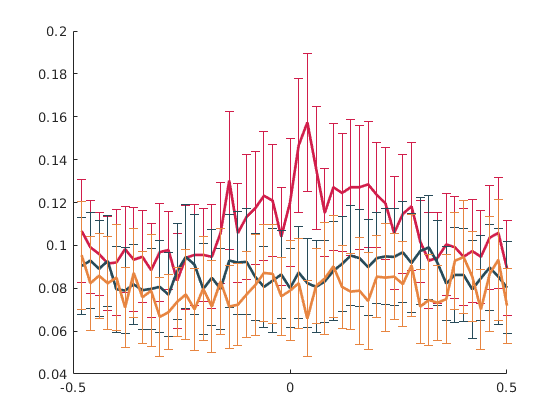

meanSound.aluminumMean = meanMatrix(aluminumEvents,1,30000);
figure; plot(mean(experiment.sound_events.fullSound(meanSound.aluminumMean)));
hold on;
meanSound.mutedMean = meanMatrix(mutedEvents,1,30000);
plot(mean(experiment.sound_events.fullSound(meanSound.mutedMean)));

meanSound.nonMean = meanMatrix(nonEvents,1,30000)
plot(mean(experiment.sound_events.fullSound(meanSound.nonMean)));

meanSound = struct with fields:
    aluminumMean: [73×400 double]


experiment.sound_events.aluminum = aluminumTimes;

Unrecognized function or variable 'y'.

experiment.sound_events.muted = mutedTimes;
experiment.sound_events.non = nonTimes;
experiment.PSTHs.alum = psth_aluminumAll;
experiment.PSTHs.muted = psth_mutedAll;
experiment.PSTHs.non = psth_nonAll;
%experiment.PSTHs.audUnits = aud_units;
experiment.PSTHs.time_vector = time_vector;

experiment.sound_events.aluminumEvents = aluminumEvents;
experiment.sound_events.mutedEvents = mutedEvents;
experiment.sound_events.nonEvents = nonEvents;

%params = '/home/ben/Z/Parameters_files/FVB/FVB103_270721_849.m';
run(params)

meanSound = struct with fields:
    aluminumMean: [126×30000 double]
       mutedMean: [334×30000 double]
         nonMean: [513×30000 double]


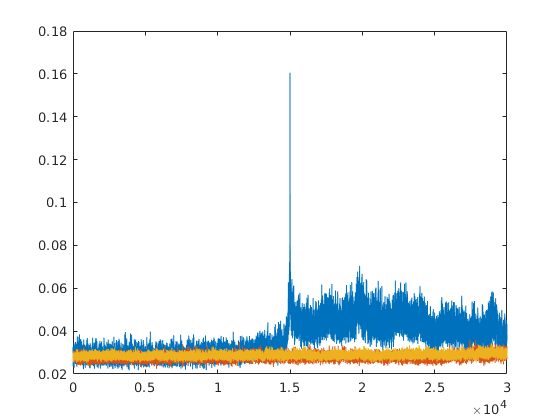

save([expName,'.mat'],'experiment')